% This live script is used to test the upsampling function
% for the ECE 434 DSP CPX3 project
%
% Author: Ben Cometto
% 20 Nov 24

clear all
close all

% This worked wonderfully before the lpf
% data = [ 1 2 2 1; 
%     3 4 3 2; 
%     5 5 4 5; 
%     6 6 6 6; 
%     6 8 6 9; 
%     7 8 7 9; 
%     9 9 8 11; 
%     11 10 9 13;
%     11 12 11 13;
%     13 14 12 16;
%     13 15 14 17;
%     14 14 15 18;
%     15 13 13 20;]

Fs = 100000;
T = 1/Fs;
N = 2000;
n = 1:2000;
t = n*T;
k = n;
df = Fs/length(k); % Fs/N
f = k*df;

data = [sin(30000*n*T); sin(45000*n*T); n; cos(20000*n*T) + 2*cos(10000*n*T) + 3*sin(25000*n*T)]';

% Prepare data
load lpf_upsample.bin -mat
data_zeros = zeros(2*height(data),width(data))

data_zeros =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


height(data_zeros)

ans =         4000


2*N

ans =         4000


tic
data_u = upsampling(data,num_upsample,data_zeros,2*N);
toc

Elapsed time is 0.003355 seconds.



FsU = 2*Fs;
nU = 1:length(data_u(:,1));
tU = nU/FsU;
kU = nU;
dfU = FsU/length(kU)

dfU =     50


fU = kU*dfU;


% ===== Analysis: Does it work on canned data =====
% Notes: fc at fs/2
%        Scaled by 1/L so multiply by L
%        Can probably speed up with lower order, and can test several other
%        methods of doing the zero padding

col = 3

col =      3


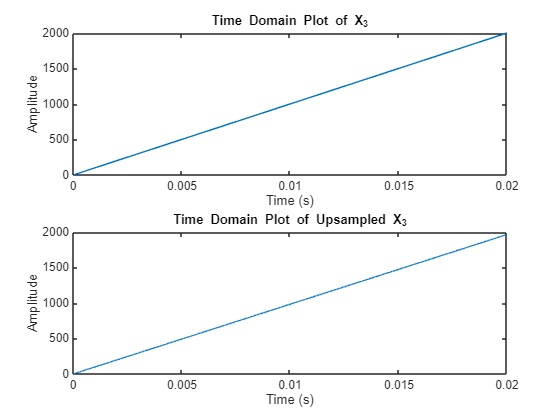


Data = abs(fft(data));
Data_U = abs(fft(data_u));

figure
subplot(2,1,1)
plot(t,data(:,col))
title(sprintf("Time Domain Plot of X_%i",col))
xlabel("Time (s)")
ylabel("Amplitude")

subplot(2,1,2)
plot(tU,data_u(:,col))
title(sprintf("Time Domain Plot of Upsampled X_%i",col))
xlabel("Time (s)")
ylabel("Amplitude")


a = 100

a =    100


b = 150

b =    150


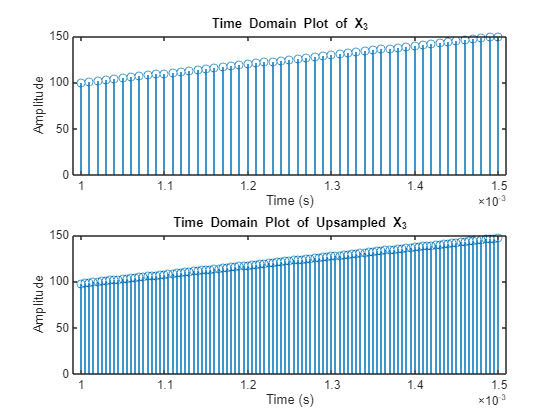

figure
subplot(2,1,1)
stem(t(a:b),data(a:b,col))
title(sprintf("Time Domain Plot of X_%i",col))
xlabel("Time (s)")
ylabel("Amplitude")

subplot(2,1,2)
stem(tU(2*a:2*b),data_u(2*a:2*b,col))
title(sprintf("Time Domain Plot of Upsampled X_%i",col))
xlabel("Time (s)")
ylabel("Amplitude")

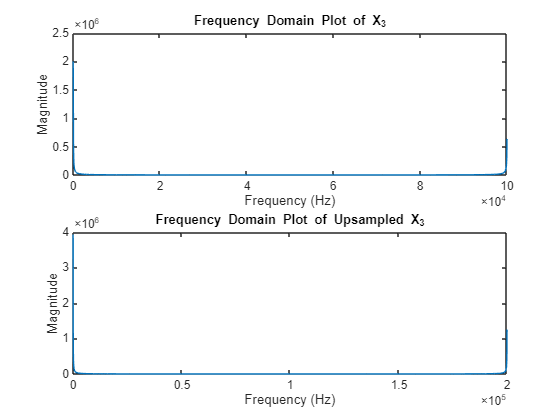




figure
subplot(2,1,1)
plot(f,Data(:,col))
title(sprintf("Frequency Domain Plot of X_%i",col))
xlabel("Frequency (Hz)")
ylabel("Magnitude")
subplot(2,1,2)
plot(fU,Data_U(:,col))
title(sprintf("Frequency Domain Plot of Upsampled X_%i",col))
xlabel("Frequency (Hz)")
ylabel("Magnitude")

% ===== Analysis: Speed =====
% notes: lots of variation... finally at 100k iterations its pretty stable
% at 18us
% in AM of 11/21 slowed down to 27us
% passing in zero vector makes it 25us (all for 200 data points)
% Actually 2000 pts:
% 243 us
% 170 us with 10 order filter
% 60-80 us with 3 order filter!
% 100 us with precomputed indexes

iterations = 10000

iterations =        10000


sum = 0;
N = 2000;

load test_data.mat
load lpf_upsample.bin -mat
data_zeros = zeros(2*height(data),width(data));
NU = 2*N;

for k=1:iterations
    time1 = tic;
    upsampling(data,num_upsample,data_zeros,NU);
    time2 = toc(time1);

    sum = sum + time2;
end

averageRuntime = sum/iterations

averageRuntime =      6.473467000000001e-05


% ===== Analysis: Real Data =====
% Notes: the data we care about is under 20KHz,
% so can use a very low order filter for speed

load test_data.mat
data;
data_zeros = zeros(2*height(data),width(data));

tic
data_u = upsampling(data,num_upsample,data_zeros,2*N)

data_u =   -0.040061305208293  -0.025989592267746  -0.003302544873802  -0.044943328065218
  -0.093833903265464  -0.060874324340678  -0.007735411380307  -0.105268859218962
  -0.112787639062936  -0.040197521652526  -0.039181382135204  -0.140160963755217
  -0.084455840086577   0.022440809417655  -0.076957114103683  -0.126669630909332
  -0.045399657231180   0.036943289080872  -0.103808239816768  -0.078567346877869
  -0.021307991434957  -0.006228976025960  -0.102073639879440  -0.027493015389875
  -0.023318236140749  -0.085059286274537  -0.072063558200109   0.000650410491220
  -0.050108168506150  -0.147697617344719  -0.033516892926151  -0.012648189028295
  -0.088446406823764  -0.162487274823049  -0.005517055952613  -0.059458172891749
  -0.113116272599097  -0.119700476368956  -0.006480722584462  -0.108990637768785


toc

Elapsed time is 0.048616 seconds.



FsU = 2*Fs;
nU = 1:length(data_u(:,1));
tU = nU/FsU;
kU = nU;
dfU = FsU/length(kU)

dfU =     50


fU = kU*dfU;

% Plotting
col = 1:4

col =      1     2     3     4


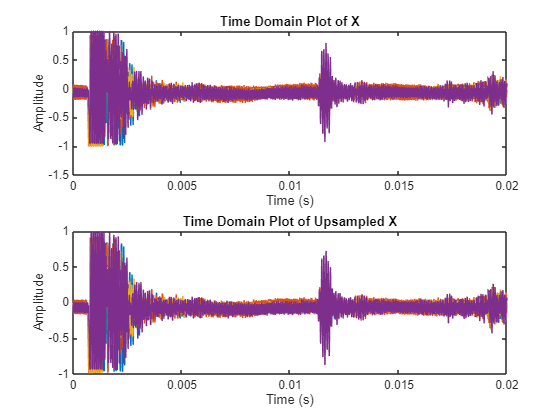


Data = abs(fft(data));
Data_U = abs(fft(data_u));

figure
subplot(2,1,1)
plot(t,data(:,col))
title(sprintf("Time Domain Plot of X"))
xlabel("Time (s)")
ylabel("Amplitude")

subplot(2,1,2)
plot(tU,data_u(:,col))
title(sprintf("Time Domain Plot of Upsampled X"))
xlabel("Time (s)")
ylabel("Amplitude")

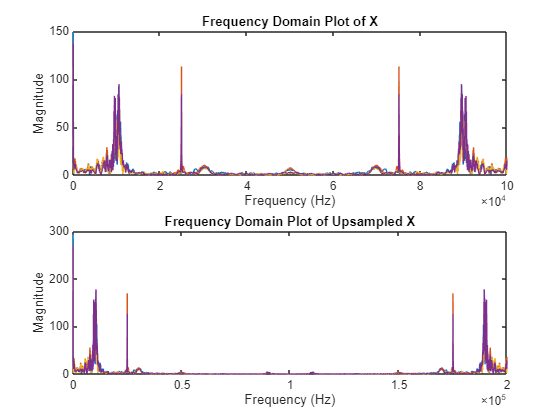



figure
subplot(2,1,1)
plot(f,Data(:,col))
title(sprintf("Frequency Domain Plot of X"))
xlabel("Frequency (Hz)")
ylabel("Magnitude")
subplot(2,1,2)
plot(fU,Data_U(:,col))
title(sprintf("Frequency Domain Plot of Upsampled X"))
xlabel("Frequency (Hz)")
ylabel("Magnitude")


% Zoom
a = 1000

a =         1000


b = 1100

b =         1100


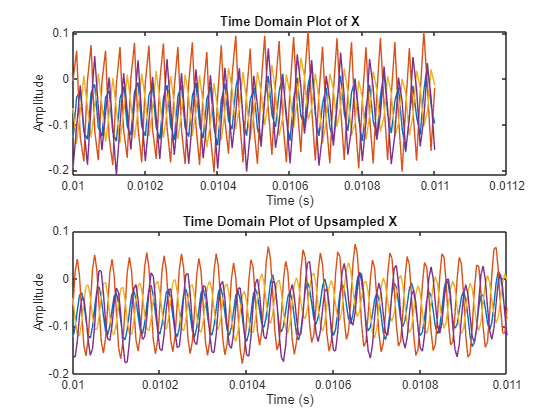


figure
subplot(2,1,1)
plot(t(a:b),data(a:b,col))
title(sprintf("Time Domain Plot of X"))
xlabel("Time (s)")
ylabel("Amplitude")

subplot(2,1,2)
plot(tU(2*a:2*b),data_u(2*a:2*b,col))
title(sprintf("Time Domain Plot of Upsampled X"))
xlabel("Time (s)")
ylabel("Amplitude")

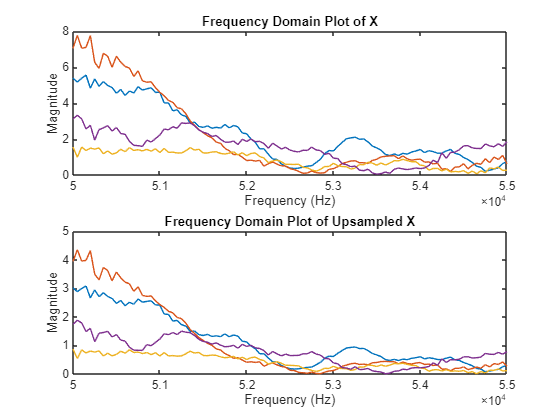



figure
subplot(2,1,1)
plot(f(a:b),Data(a:b,col))
title(sprintf("Frequency Domain Plot of X"))
xlabel("Frequency (Hz)")
ylabel("Magnitude")
subplot(2,1,2)
plot(fU(a:b),Data_U(a:b,col))
title(sprintf("Frequency Domain Plot of Upsampled X"))
xlabel("Frequency (Hz)")
ylabel("Magnitude")